Modern Control Project Phase 1

Fatemeh Naeinian     SID=810198479

part 1

syms x1 x2 x3 u;

R = 50; 
L = 0.2; 
g = 9.8; 
M = 0.4+0.079; 
c = 0.3; 
fv = 0.04; 
ystar = 0.06;

eq1= x2 == 0;
eq2= -g+c*x3^2/(0.1-x1)/M-fv*x2/M == 0;
eq3= 1/L*(-R*x3+u) == 0;
eq4= x1 == 0.06;
sol=solve([eq1,eq2,eq3,eq4],[x1 x2 x3 u]);

x1star = double(sol.x1)

x1star =    0.060000000000000
   0.060000000000000


x2star = double(sol.x2)

x2star =      0
     0


x3star = double(sol.x3)

x3star =   -0.791134206903818
   0.791134206903818


ustar = double(sol.u)

ustar =  -39.556710345190908
  39.556710345190908


part 2

x1star = 0.06;
x2star = 0;
x3star = 0.791134207;
ustar = -39.55671034;
ystar = x1star;

A = [0, 1, 0;c/M*x3star^2/(0.1-x1star)^2, -fv/M, -c/M*x3star*2/(0.1-x1star); 0, 0, -R/L];
B = [0 0, 1/L]';
C = [1, 0, 0];
D = 0;

x = [x1-x1star, x2-x2star, x3-x3star]';
xdot = A*x + B*u

$$xdot = \left(\begin{array}{c} \bar{x_{2}}\\ \frac{538760697741239\,\bar{x_{1}}}{2199023255552}-\frac{40\,\bar{x_{2}}}{479}-\frac{6973418032056207\,\bar{x_{3}}}{281474976710656}+\frac{155287198565716080491453265151827}{31691265005705735037417580134400}\\ 5\,u-250\,\bar{x_{3}}+\frac{445368964980656625}{2251799813685248} \end{array}\right)$$

y = C*x + D*u - ystar

$$y = \bar{x_{1}}-\frac{3}{25}$$

part 3

landa = eig(A);
display(landa)

landa = 1.0e+02 *

   0.156107778806921
  -0.156942851875815
  -2.500000000000000


part 4

Controlable = [B, A*B, A*A*B]

Controlable = 1.0e+05 *

                   0                   0  -0.001238727881524
                   0  -0.001238727881524   0.309785413210357
   0.000050000000000  -0.012500000000000   3.125000000000000


det(Controlable)

ans =     -7.672233822324783e+04


Observable = [C; C*A; C*A*A]

Observable = 1.0e+02 *

   0.010000000000000                   0                   0
                   0   0.010000000000000                   0
   2.450000000595714  -0.000835073068894  -0.247745576304802


det(Observable)

ans =  -24.774557630480160


s=tf('s');
gs=C*((s.*eye(3)-A)^-1)*B+D

gs =
 
                 -123.9
  ------------------------------------
  s^3 + 250.1 s^2 - 224.1 s - 6.125e04
 
Continuous-time transfer function.



part 5

syms t
eAt = vpa(expm(A * t), 4)

$$eAt = \left(\begin{array}{ccc} 0.5013\,{\mathrm{e}}^{15.61\,t}+0.4987\,{\mathrm{e}}^{-15.69\,t} & 0.03194\,{\mathrm{e}}^{15.61\,t}-0.03194\,{\mathrm{e}}^{-15.69\,t} & 0.003378\,{\mathrm{e}}^{-15.69\,t}-0.0003981\,{\mathrm{e}}^{-250.0\,t}-0.00298\,{\mathrm{e}}^{15.61\,t}\\ 7.826\,{\mathrm{e}}^{15.61\,t}-7.826\,{\mathrm{e}}^{-15.69\,t} & 0.4987\,{\mathrm{e}}^{15.61\,t}+0.5013\,{\mathrm{e}}^{-15.69\,t} & 0.09952\,{\mathrm{e}}^{-250.0\,t}-0.04651\,{\mathrm{e}}^{15.61\,t}-0.05301\,{\mathrm{e}}^{-15.69\,t}\\ 0 & 0 & {\mathrm{e}}^{-250.0\,t} \end{array}\right)$$

% [Q,j] = eig(A);
% TM = vpa(Q*exp(j*t)*inv(Q),3)

part 6

s=tf('s');
gs=C*((s.*eye(3)-A)^-1)*B+D

gs =
 
                 -123.9
  ------------------------------------
  s^3 + 250.1 s^2 - 224.1 s - 6.125e04
 
Continuous-time transfer function.



z = zero(gs)


z =

  0×1 empty double column vector



p = pole(gs)

p = 1.0e+02 *

  -2.500000000000000
   0.156107778806922
  -0.156942851875815


part 7 & 8

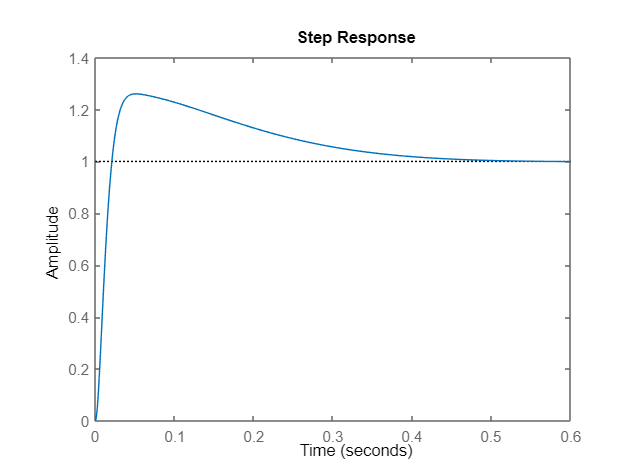

con = pid(-2.94e03, -1.28e04, -169);
cg = con * gs;
T = feedback(cg, 1);
step(T)

controller = pidtune(gs,'PID')

controller =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = -2.94e+03, Ki = -1.28e+04, Kd = -169
 
Continuous-time PID controller in parallel form.



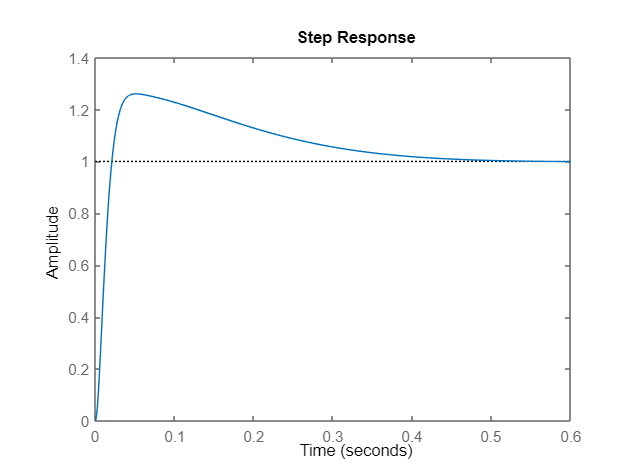

cg = controller * gs;
T = feedback(cg, 1);
step(T)